% LAB 1

clear
load chips20
load Ad
load Ad2
load illum


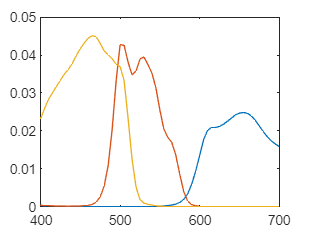

% 1.1

L = 400:5:700;
plot(L, Ad) % blues, greens, little reds

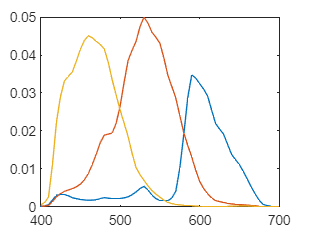

plot(L, Ad2) % greens, blues, little red

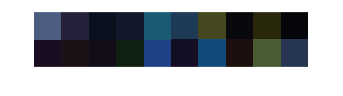

% 1.2

d = Ad' * (chips20.*CIED65)';
d2 = Ad2' * (chips20.*CIED65)';

save("RGB_raw_D65", "d")

showRGB(d')

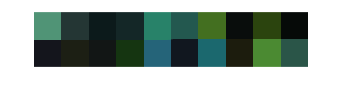

showRGB(d2')

% 2.1
e = ones(1,61);

fact1 = Ad' * e'

fact1 =     0.4635
    0.5646
    0.8585


fact2 = Ad2' * e'

fact2 =     0.4726
    0.8747
    0.7420


% blues and greens reduced most 

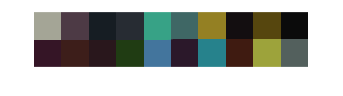

% 2.2
calibrRGB = d ./ fact1;
showRGB(calibrRGB')

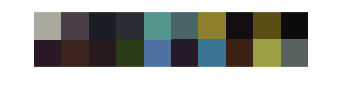

save("RGB_cal_D65","calibrRGB");

calibrRGB2 = d2 ./ fact2;
showRGB(calibrRGB2')

% Much better and similar to eachother

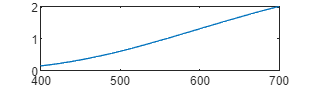

% 2.3
plot(L, CIEA) %Mer rött/oranget

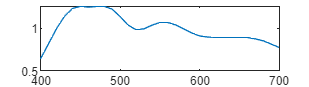

plot(L, CIED65) %Mer neutralt

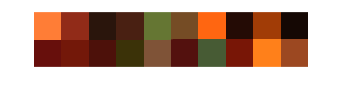

% 2.4
d = Ad' * (chips20.*CIEA)';
dnorm = d ./ fact1;
showRGB(dnorm')


showRGB(calibrRGB')

% makes sense ig? more reddish tones, calibration is not based on light
% source

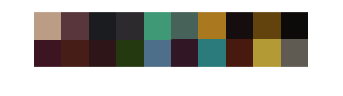

% 2.5
e1 = ones(1,61) .* CIED65;
e2 = ones(1,61) .* CIEA;

d65 = Ad' * (chips20.*CIED65)';
dA = Ad' * (chips20.*CIEA)';

fact65 = Ad' * e1';
factA = Ad' * e2';

d65norm = d65 ./ fact65;
dAnorm = dA ./ factA;

showRGB(d65norm')

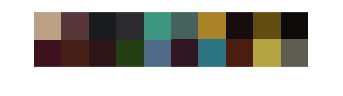

showRGB(dAnorm')


% Much more similar, a LITTLE different

% 3.1 konvertera spektraldata för chips till xyz sanna färger, reference vals
load xyz
k = 100 / (CIED65*xyz(:,2)) % factor so Y=100

k = 4.6460

d = xyz' .* k * (chips20.*CIED65)'

d =    66.5076   29.1415   10.3354   17.0944   37.2524   31.4696   51.8681    7.1516   35.7168    4.5704   14.7977   21.2515   13.6952   19.1563   34.5574   13.8335   26.8255   20.8937   59.1042   36.1553
   67.2653   25.9561   10.4588   16.8158   49.3000   35.3276   57.1830    6.4429   38.2742    4.5382   10.4425   18.0936   11.4180   25.1057   36.1143   10.5687   34.9493   17.7770   67.6801   37.2942
   61.0087   28.3929   14.4753   20.9340   50.2915   40.5003   10.0020    6.4265    5.4609    4.4085   16.5167   10.6582   11.4388    7.5209   65.7332   18.0017   54.8397    6.5922   17.7720   37.8082



save("XYZ_D65_ref", "d");

% 3.2 kalibrerade rgb till xyz, jämför med ref
clear
load M_XYZ2RGB
load RGB_cal_D65
load XYZ_D65_ref

invMat = inv(M_XYZ2RGB);
XYZ_est = invMat * calibrRGB;

[maxDeltaE, meanDeltaE] = MeanMax(XYZ_est', d')

maxDeltaE = 31.6232

meanDeltaE = 12.6418

% medel skillnader? mean nästan lika hög som max

% 3.3 spektral senstivitet för Ad vs människosyn (xyz)
load Ad
load xyz

x = 400:5:700

x =    400   405   410   415   420   425   430   435   440   445   450   455   460   465   470   475   480   485   490   495   500   505   510   515   520   525   530   535   540   545   550   555   560   565   570   575   580   585   590   595   600   605   610   615   620   625   630   635   640   645


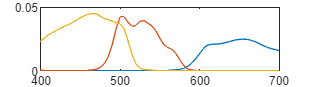

clf
plot(x, Ad)

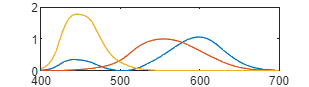


plot(x, xyz)

% not entirely similar, need to make camera vision more like humans

% 3.4 metoder för bättre mappnign RGB to XYZ

A = pinv(calibrRGB')*d';
XYZconv = calibrRGB' * A;

[maxDeltaEconv, meanDeltaEconv] = MeanMax(XYZconv, d')

maxDeltaEconv = 5.8376

meanDeltaEconv = 2.1977

%3.5 metoder för bättre mappnign RGB to XYZ

Aop = Optimize_poly(calibrRGB,d);
XYZconvlr = Polynomial_regression(calibrRGB,Aop);

[maxDeltaEconv2, meanDeltaEconv2] = MeanMax(XYZconvlr', d')

maxDeltaEconv2 = 3.1053

meanDeltaEconv2 = 1.0238

save("XYZconvlr", "XYZconvlr")
% är det ens rätt??

function [maxDeltaE, meanDeltaE] =  MeanMax(XYZ_est, XYZ_ref)
    [CIE_est_x, CIE_est_y, CIE_est_z] = xyz2lab(XYZ_est(:,1),XYZ_est(:,2),XYZ_est(:,3));

    [CIE_ref_x, CIE_ref_y, CIE_ref_z] = xyz2lab(XYZ_ref(:,1),XYZ_ref(:,2),XYZ_ref(:,3));
    
    deltaE = sqrt((CIE_ref_x-CIE_est_x).^2 + (CIE_ref_y-CIE_est_y).^2 + (CIE_ref_z-CIE_est_z).^2);
    
    maxDeltaE = max(deltaE);
    meanDeltaE = mean(deltaE);
end
